format long 
syms y(x) f_d(s,t,z) g_d(s,t,z)

% find the exact solutions function first 
Dy = diff(y);

% plug in the ode equation
ode = diff(y,x,2) + 0.25*diff(y,x,1) == 8;

% input the ode boundary conditions
cond1 = y(0) == 0;
cond2 = y(10) == 0;

% solve for the pde
conds = [cond1 cond2];
ySol(x) = dsolve(ode,conds);
ySol = simplify(ySol)

$$ySol(x) = 32\,x+\frac{320\,{\mathrm{e}}^{\frac{5}{2}-\frac{x}{4}}}{{\mathrm{e}}^{5/2}-1}-\frac{64\,\left(3\,{\mathrm{e}}^{5/2}+2\right)}{{\mathrm{e}}^{5/2}-1}-128$$

Compute the shooting method

% set the step size
h = 1;

% set the range for the data points
x = 0:h:10;

% boundary conditions
y_0 = 0;
y_10 = 0;

% input the derrivative functions associated the ODE 
f_d(s,t,z) = z;
g_d(s,t,z) = 8 - z/4;

% guess random points to start so we can interpolate a distance
yd_top = 1;
y_top = 0;

yd_bottom = 0;
y_bottom = 0;
while 1
    % do the process for the top pt
    % create the list of y, z points that will be used and insert the ICs
    y_rk_top = zeros(length(x),1);
    y_rk_top(1) = y_0;
    
    z_rk_top = zeros(length(x),1);
    z_rk_top(1) = yd_top;
    
    % compute the runge kutta
    for i=1:length(y_rk_top)-1
        l1 = g_d(x(i),y_rk_top(i),z_rk_top(i));
        k1 = f_d(x(i),y_rk_top(i),z_rk_top(i));
        l2 = g_d(x(i)+h/2,y_rk_top(i)+k1*h/2,z_rk_top(i)+l1*h/2);
        k2 = f_d(x(i)+h/2,y_rk_top(i)+k1*h/2,z_rk_top(i)+l1*h/2);
        l3 = g_d(x(i)+h/2,y_rk_top(i)+k2*h/2,z_rk_top(i)+l2*h/2);
        k3 = f_d(x(i)+h/2,y_rk_top(i)+k2*h/2,z_rk_top(i)+l2*h/2);
        l4 = g_d(x(i)+h,y_rk_top(i)+k3*h,z_rk_top(i)+l3*h);
        k4 = f_d(x(i)+h,y_rk_top(i)+k3*h,z_rk_top(i)+l3*h);
        
        y_rk_top(i+1) = y_rk_top(i) + h*(k1+2*k2+2*k3+k4)/6;
        z_rk_top(i+1) = z_rk_top(i) + h*(l1+2*l2+2*l3+l4)/6;
    end
    y_top = y_rk_top(length(x));
    
    % repeat for bottom point
    % create the list of y, z points that will be used and insert the ICs
    y_rk_bottom = zeros(length(x),1);
    y_rk_bottom(1) = y_0;
    
    z_rk_bottom = zeros(length(x),1);
    z_rk_bottom(1) = yd_bottom;
    
    % compute the runge kutta
    for i=1:length(y_rk_bottom)-1
        l1 = g_d(x(i),y_rk_bottom(i),z_rk_bottom(i));
        k1 = f_d(x(i),y_rk_bottom(i),z_rk_bottom(i));
        l2 = g_d(x(i)+h/2,y_rk_bottom(i)+k1*h/2,z_rk_bottom(i)+l1*h/2);
        k2 = f_d(x(i)+h/2,y_rk_bottom(i)+k1*h/2,z_rk_bottom(i)+l1*h/2);
        l3 = g_d(x(i)+h/2,y_rk_bottom(i)+k2*h/2,z_rk_bottom(i)+l2*h/2);
        k3 = f_d(x(i)+h/2,y_rk_bottom(i)+k2*h/2,z_rk_bottom(i)+l2*h/2);
        l4 = g_d(x(i)+h,y_rk_bottom(i)+k3*h,z_rk_bottom(i)+l3*h);
        k4 = f_d(x(i)+h,y_rk_bottom(i)+k3*h,z_rk_bottom(i)+l3*h);
        
        y_rk_bottom(i+1) = y_rk_bottom(i) + h*(k1+2*k2+2*k3+k4)/6;
        z_rk_bottom(i+1) = z_rk_bottom(i) + h*(l1+2*l2+2*l3+l4)/6;
    end
    y_bottom = y_rk_bottom(length(x));
    
    if y_top*y_bottom < 0
        break;
    else
        yd_bottom = yd_bottom - 10;
        yd_top = yd_top + 1;
    end
end

p = yd_top + (yd_bottom-yd_top)*(y_10 - y_top)/(y_bottom-y_top)

p =  -55.154820877021550


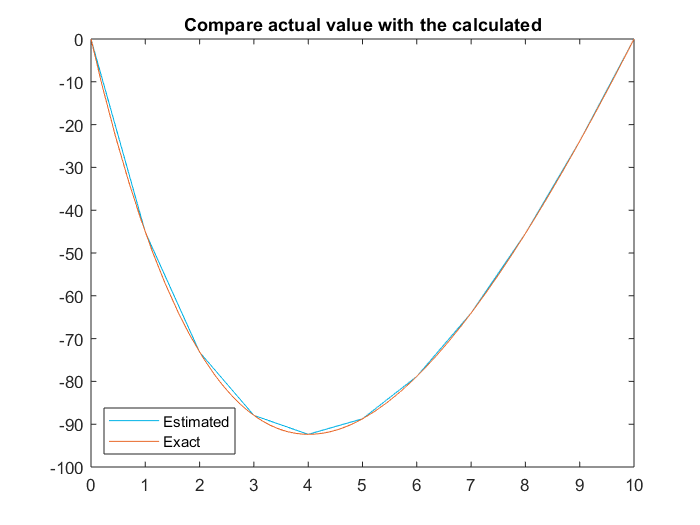


% create the list of points and put in the initial condition y = 2, z = 0
y_rk = zeros(length(x),1);
y_rk(1) = y_0;

z_rk = zeros(length(x),1);
z_rk(1) = p;

% compute the runge kutta
for i=1:length(y_rk)-1
    l1 = g_d(x(i),y_rk(i),z_rk(i));
    k1 = f_d(x(i),y_rk(i),z_rk(i));
    l2 = g_d(x(i)+h/2,y_rk(i)+k1*h/2,z_rk(i)+l1*h/2);
    k2 = f_d(x(i)+h/2,y_rk(i)+k1*h/2,z_rk(i)+l1*h/2);
    l3 = g_d(x(i)+h/2,y_rk(i)+k2*h/2,z_rk(i)+l2*h/2);
    k3 = f_d(x(i)+h/2,y_rk(i)+k2*h/2,z_rk(i)+l2*h/2);
    l4 = g_d(x(i)+h,y_rk(i)+k3*h,z_rk(i)+l3*h);
    k4 = f_d(x(i)+h,y_rk(i)+k3*h,z_rk(i)+l3*h);
    
    y_rk(i+1) = y_rk(i) + h*(k1+2*k2+2*k3+k4)/6;
    z_rk(i+1) = z_rk(i) + h*(l1+2*l2+2*l3+l4)/6;
end

plot(x,y_rk,'Color',[0,0.7,0.9])
hold on 
fplot(ySol,[0,10],'Color',[0.9100,0.4100,0.1700])
legend({'Estimated','Exact'},'Location','southwest')
title('Compare actual value with the calculated')
hold off

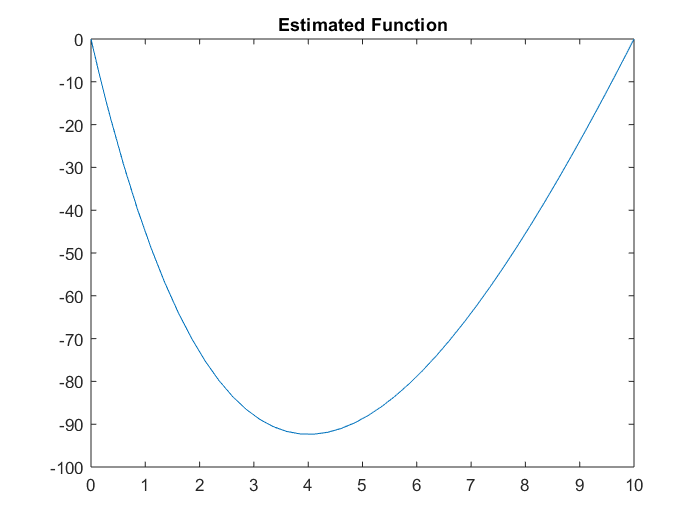

x =  -55.154046402018011


y =      1.776356839400250e-14


z =      1




% DONT NEEED
x0 = 0.5;
% compute the fzero of the function computed 
[x,y,z] = fzero(@F,x0)

function [f,x_coord,y_coord]=F(s) % define the shooting functions
% using the matlab ode45 
[x,y] = ode45(@de,[0 10], [0 s]);

% use the initial condition for the end boundary conditio
y_10 = 0;
f = y(end,1) - y_10;
% plot the output
% hold on
plot(x,y(:,1))
title('Estimated Function')
x_coord = x;
y_coord = y(:,1);
end

% systems of differential equations
function y=de(t,x)
% since second order find the 2 functions for he DE 
y = zeros(2,1);

y(1) = x(2);
y(2) = 8 - x(2)/4;
end





